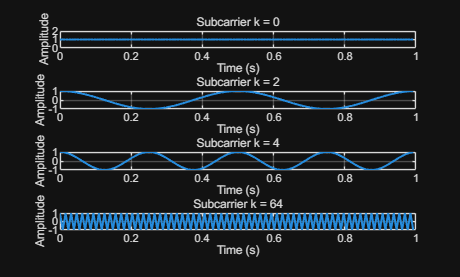

% OFDM Subcarrier Analysis and Orthogonality Check
% Parameters setup
N = 128;          % Number of subcarriers
T = 1;            % OFDM symbol duration (normalized to 1 for simplicity)
fs = N/T;         % Sampling frequency
n = 0:N-1;        % Time index vector
t = n/fs;         % Time vector

% Generate subcarriers for k = 0, 2, 4, and 64
k_values = [0 2 4 64];
x = zeros(length(k_values), N);  % Matrix to store subcarrier signals

% Generate the complex exponential signals for each k
for i = 1:length(k_values)
    k = k_values(i);
    fk = k/T;     % Subcarrier frequency
    x(i,:) = exp(1j*2*pi*fk*t);  % Complex exponential signal
end

% Create subplots to visualize the real part of each subcarrier
figure(1);
for i = 1:length(k_values)
    subplot(4,1,i);
    plot(t, real(x(i,:)), 'LineWidth', 1.5);
    grid on;
    title(['Subcarrier k = ' num2str(k_values(i))]);
    xlabel('Time (s)');
    ylabel('Amplitude');
end


% Calculate correlation matrix C
C = zeros(length(k_values));
for i = 1:length(k_values)
    for j = 1:length(k_values)
        % Calculate correlation using the formula C(i,j) = (1/N)∑x_i[n]x_j*[n]
        C(i,j) = (1/N) * sum(x(i,:) .* conj(x(j,:)));
    end
end

% Display correlation matrix
disp('Correlation Matrix C:');

Correlation Matrix C:


disp(C);

   1.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i
  -0.0000 + 0.0000i   1.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i
  -0.0000 + 0.0000i  -0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 - 0.0000i
   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i




% Verify orthogonality by checking if C is approximately identity matrix
disp('Maximum deviation from ideal correlation:');

Maximum deviation from ideal correlation:


disp(max(max(abs(C - eye(length(k_values))))));

   8.6211e-16

